# 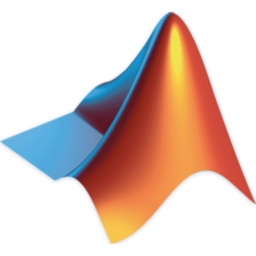

# Data Visualization with Matlab

## What does "Data Visualization" Mean?

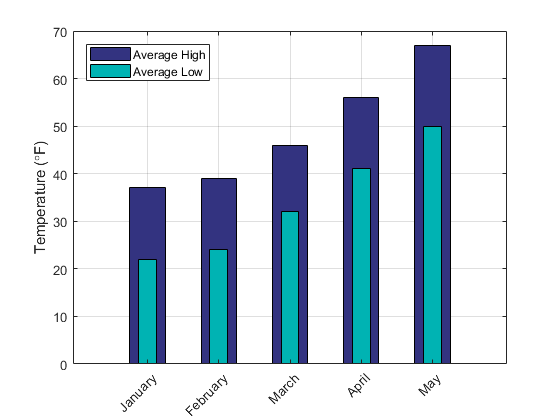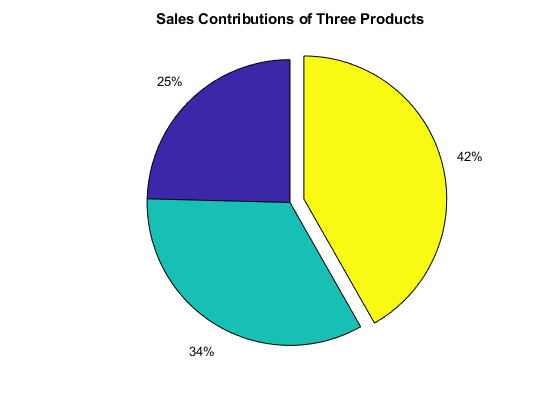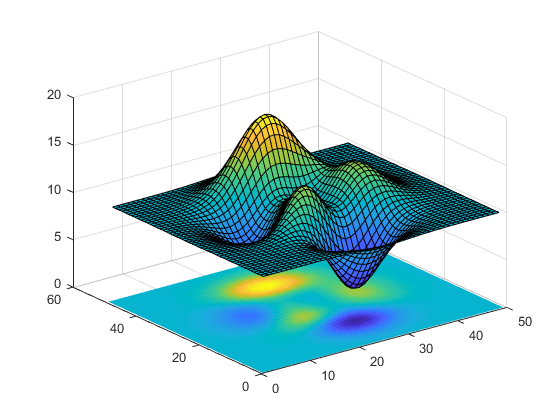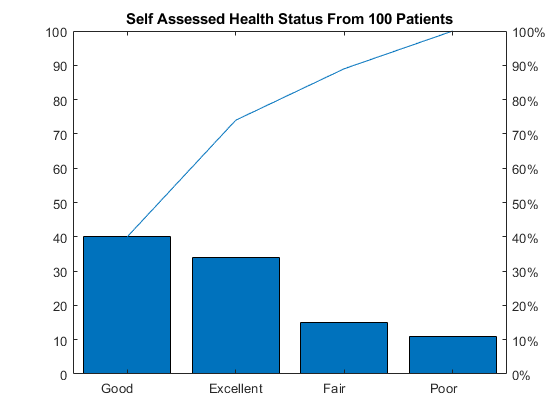

Communicating information graphically and intuitively

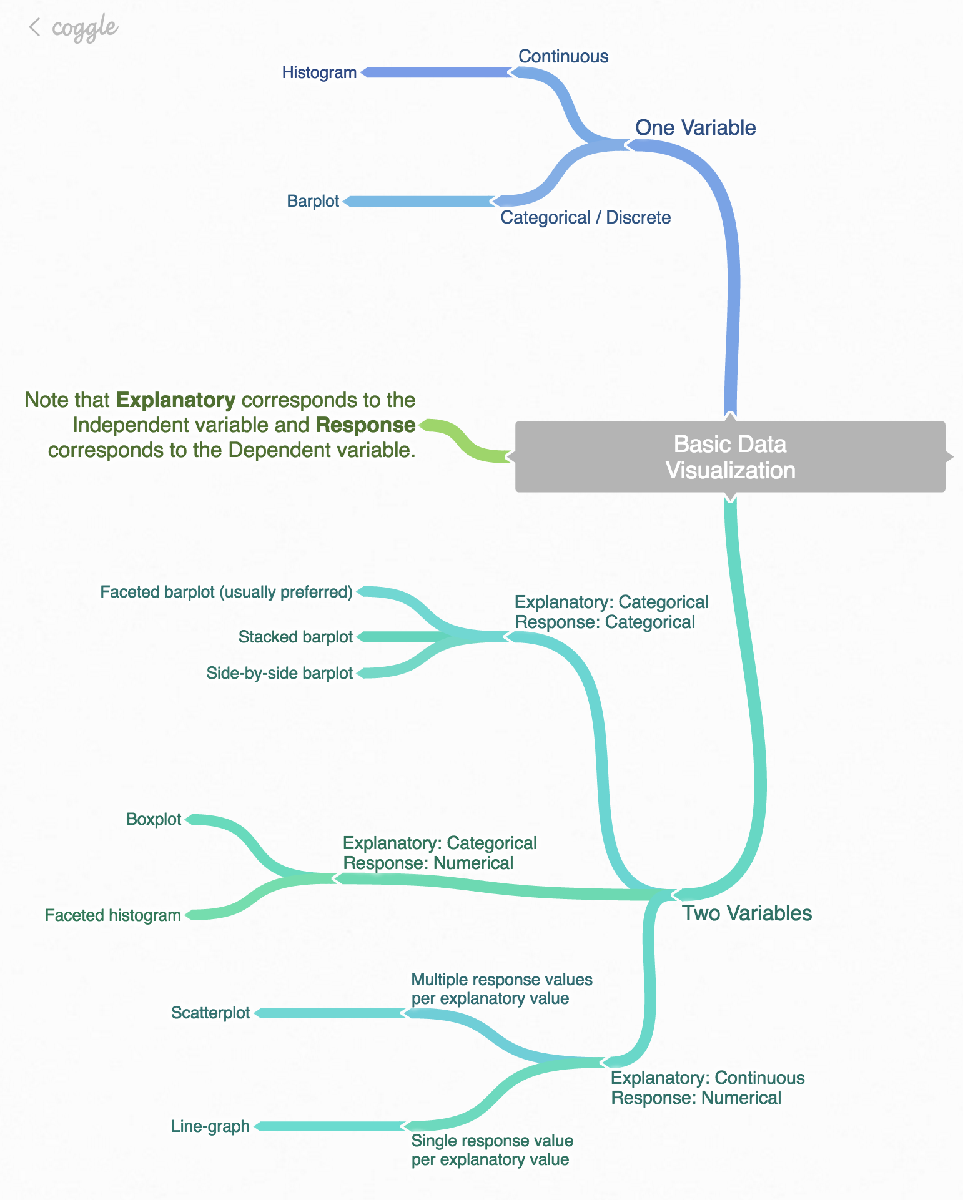

Credit: [http://moderndive.com/3-viz.html#grammarofgraphics](http://moderndive.com/3-viz.html#grammarofgraphics)

## Workshop Overview

- The Ins & Outs of the `plot` Function

- Formatting and Annotation

- Log-Scaled Axes

- Distribution Data Viz

- Discrete Data Viz

- Multivariate Data Viz

- Surface and Mesh Plots

- Images

- Animation

- Saving Figures

## The Ins and Outs of the `plot` Function

Basic Line Plot

Line plots are great for visualizing time series data or data that has a single response value per explanatory value.

Examples: variation in number of living cells over a 7-day timespan, pressure of air versus altitude

x = -pi:pi/10:pi;
y = sin(x);

plot(x,y)

First argument of `plot` is x-axis variable.

Second argument is y-axis variable.

Plotting Multiple Lines

There are several ways to plot multiple lines on one figure.

Method 1:

clf; % clears the current figure window

x = linspace(-2*pi, 2*pi); % creates a vector of 100 linearly spaced points between -2pi and 2pi
y1 = sin(x);
y2 = cos(x);

plot(x, y1, x, y2)         % plot can take multiple line inputs in pairs


Method 2:

figure;          % creates a new figure window
plot(x, y1)
hold on          % holds the current figure, will not overwrite
plot(x, y2)
hold off         % turns hold off

Plot from a Matrix

y = magic(4)

figure;
plot(y)

When plotting a matrix, each column is a line. Row index is the x-axis variable.

Line Style Specifications

x = 0:pi/10:2*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);

plot(x,y1,x,y2,'--',x,y3,':')     % '--' will plot y2 as a dashed line, ':' will plot y3 as a dotted line

More Line Specifications: Line Style, Color, and Marker

Line specifications can be written in any order. (`'g--*'` = `'*g--'`)

plot(x,y1,'g',x,y2,'b--o',x,y3,'c*')      % 'g' plots y1 as a green line, 
                                          % 'b--o' plots y2 as a blue dashed line with open circle markers, 
                                          % 'c*' plots y3 as cyan asterisk markers with no line

Markers at Specific Data Points

x = linspace(0,10);              % creates a vector x with 100 linearly spaced points between 0 and 10
y = sin(x);
plot(x,y,'-o', 'MarkerIndices', 1:5:length(y))    % plots y as a solid line with open circle markers at every 5 data points

Subplots

x = 0:pi/10:5*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
y4 = sin(x-0.75);

% Create 2 rows and 2 columns of subplots (2x2 = 4 total plots)
subplot(2,2,1); plot(x,y1) % plots y1 in the first subplot
subplot(2,2,2); plot(x,y2) % plots y2 in the first subplot
subplot(2,2,3); plot(x,y3) % plots y3 in the first subplot
subplot(2,2,4); plot(x,y4) % plots y4 in the first subplot

Handles

clf
x = linspace(-2*pi,2*pi);
y = sin(x);
p = plot(x,y);

p.Marker = '*';       % add asterisk markers
p.Color = 'black';    % change line color to black

Multiple Lines in One Handle

x = linspace(-2*pi,2*pi);
y1 = sin(x);
y2 = cos(x);
p = plot(x,y1,x,y2);

p(1).LineWidth = 3;   % change line width of y1 to 3
p(2).Marker = '*';    % add asterisk markers to y2 

## Plot Customization

Typically, customization is achieved with the following format:

`plot(x, y, 'PropertyName', Value)`

or

`p = plot(x,y);`

`p.PropertyName = Value;`

For multiple properties:

`plot(x, y, 'PropertyName1', Value1, ...`

`           'PropertyName2', Value2, ...`

                        `'PropertyName3', Value3)`

For a full list of properties: 

[https://www.mathworks.com/help/matlab/ref/plot.html#namevaluepairs](https://www.mathworks.com/help/matlab/ref/plot.html#namevaluepairs)

[https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

## Formatting and Annotation

You can use the GUI or the command line!

**Formatting your figure in the GUI**

- Click the Plot Tools  button in the Figure window or run the `plottools` command from the command line.

- Add the Figure Palette and Plot Browser to your Plot Tools Editor by clicking them in the Desktop menu of the Figure window.

- Click the Property you want to edit, and modify as desired.

- To save the properties of your figure to a function, click **File **--> **Generate Code. **You can use this function with other data too.

- **Optional:** Rename the generated function to something more descriptive for later use.

- For publication figures, you can edit the color scheme, resolution, etc by clicking **File **--> **Export Setup... **After selecting your options, click **Apply to Figure**, then click **Export** and choose the format you'd like to export your figure as.

The rest of this section will cover how to modify your figure in the command line.

Plot Title and Axes Labels

x = linspace(0,10,150);
y = cos(5*x);

figure
plot(x,y)

title('My Cosine Plot')
xlabel('x')
ylabel('cos(5x)')

Like with plots, you can use Handles for plot titles and axes labels. 

t = title('My Plot', 'FontSize', 24);
t.Color = 'r';

More info on titles and axes can be found here:

[https://www.mathworks.com/help/matlab/ref/title.html](https://www.mathworks.com/help/matlab/ref/title.html)

[https://www.mathworks.com/help/matlab/ref/xlabel.html](https://www.mathworks.com/help/matlab/ref/xlabel.html) , [https://www.mathworks.com/help/matlab/ref/ylabel.html](https://www.mathworks.com/help/matlab/ref/ylabel.html) , [https://www.mathworks.com/help/matlab/ref/zlabel.html](https://www.mathworks.com/help/matlab/ref/zlabel.html)

Axes Limits

You can individually set the axis limits for each axis or set all of them at the same time.

x = linspace(0,10);
y = sin(x);
figure;
plot(x,y)

% Method 1: Set Axes Limits Individually
figure;
plot(x,y)
xlim([0,5])
ylim([-2,2])

% Method 2:
figure;
plot(x,y)
axis([0,10,-2,2])   % axis reads the limits as [X-min, X-max, Y-min, Y-max]

Tick Marks

x = linspace(0,10);
y = x.^2;
plot(x,y)
grid on             % grid turns on grid lines based on tick marks

figure;
plot(x,y)
xticks([0,5,10])
xticklabels({'x=0','x=5','x=10'})
yticks([0,20,40,60,80,100])
grid on

Plot Legend

x = -pi:pi/20:pi;
y1 = sin(x);
plot(x,y1)

hold on 
y2 = cos(x);
plot(x,y2,'--')
hold off

legend('sin(x)','cos(x)')
% If you want to alter legend properties in the legend command,
% then put your legend names in a cell (curly braces { })
figure;
plot(x,y1,x,y2)
lgd = legend({'sin(x)','cos(x)'},'FontSize',18);
lgd.Location = 'best';
figure;
plot(x,y1,x,y2)
lgd = legend({'sin(x)','cos(x)'},'FontSize',18);
lgd.Location = 'northwest';

For more info on legends:

[https://www.mathworks.com/help/matlab/ref/legend.html](https://www.mathworks.com/help/matlab/ref/legend.html)

Text Descriptions

x = 0:pi/20:2*pi;
y = sin(x);

figure;
plot(x,y)
text(pi,0,'sin(\pi)')
figure
plot(x,y)
text(pi,0,'\leftarrow sin(\pi)')

More on adding text to plots:

[https://www.mathworks.com/help/matlab/ref/text.html](https://www.mathworks.com/help/matlab/ref/text.html)

Adding Lines to a Plot

x = linspace(0,10);
y = sin(x);

plot(x,y)
line([0,10],[0 0]) % Add a horizontal line at y = 0, where X-min = 0, X-max = 10 
clf
plot(x,y)
% You can also define the x and y coordinates before running the line command.
lx = [0 10];
ly = [0 0];
l = line(lx,ly);
l.Color = 'r';
l.LineWidth = 2;
l.LineStyle = '--';

Adding Rectangles to a Plot

x = linspace(0,10);
y = sin(x);

plot(x,y)
% The rectangle function reads position as [Bottom Left Corner X, Bottom Left Corner Y, width, height]
rectangle('Position',[2.5,-0.2,1,0.4])

clf
plot(x,y)
rectangle('Position',[2,-1,2,2], 'Curvature',0.2)
axis equal     % curvature is not accurately depicted unless x and y axes are on the same scale

Annotations

plot(1:10, 1:10)

% The annotation command uses normalized coordinates
x = [0.3, 0.5]; % x = [left coordinate of text arrow, right coordinate of text arrow]
y = [0.6, 0.5]; % y = [arrow height at left coordinate, arrow height at right coordinate]
annotation('textarrow',x,y,'String','y = x')
annotation('textbox',[0.2,0.5,0.3,0.3],'String','My Text','FitBoxToText','on') % coordinates are read same as rectangle command
                                                                               % FitBoxToText makes the box tight around text
annotation('rectangle',[0.45 0.45 0.1 0.1],'Color','red')
annotation('rectangle',[0.6, 0.6,0.1,0.1],'FaceColor','blue','FaceAlpha',0.2)
annotation('ellipse',[0.6, 0.6,0.1,0.1])

For more on annotation, see the documentation here:

[https://www.mathworks.com/help/matlab/ref/annotation.html](https://www.mathworks.com/help/matlab/ref/annotation.html)

## Log-Scaled Axes

Plot using a Logarithmic Scale

x = logspace(-1,2);    % create a vector of 100 logarithmically spaced points from 10^-1 to 10^2
y = exp(x);            % exp(x) command is equivalent to e^x

plot(x,y)
figure
loglog(x,y)

Plot with only one Logarithmically Scaled Axis

`semilogx: `log-scale x-axis

x = 0:1000;
y = log(x);

plot(x,y)
semilogx(x,y)

`semilogy:` log-scale y-axis

x = 0:0.1:10;
y = exp(x);

plot(x,y)
semilogy(x,y)

## Distribution Data Viz

The plots in the following section are great for visualizing distributions or proportions in your data.

For full documentation:

[https://www.mathworks.com/help/matlab/pie-charts-bar-plots-and-histograms.html](https://www.mathworks.com/help/matlab/pie-charts-bar-plots-and-histograms.html)

Bar Graphs

Bar graphs are good for displaying categorical data, e.g how much of something in different categories

Examples: Number of events per year, number of students who applied and were admitted per graduating class

clear

y = [5, 10, 15, 20, 25, 30];
bar(y)
x = [1994, 1996, 1998, 2000, 2002, 2004];

bar(x,y)
y = [5, 10, 15; 20, 25, 30]
bar(y)
c = categorical({'1990s','2000s'});

bar(c,y)
bar(c,y,'stacked')

For more on bar graphs, see the documentation here:

[https://www.mathworks.com/help/matlab/ref/bar.html](https://www.mathworks.com/help/matlab/ref/bar.html)

Histograms

Histograms are great for displaying the distribution of continuous data.

Examples: showing the distribution of test scores, ages, etc.

clear

load patients.mat

histogram(Age)
histogram(Age,10)
histogram(Age,[25,30,35,40,45,50])

More info on histograms:

[https://www.mathworks.com/help/matlab/ref/histogram.html](https://www.mathworks.com/help/matlab/ref/histogram.html)

Pie Charts

Pie charts are great for showing categorical subdivisions, or parts to a whole.

Examples: Proportion of triage levels of patients admitted to the ER, percentage of votes gained by candidates

catLocation = categorical(Location);  % convert Location from a cell to a categorical variable
pie(catLocation)
explode = 'VA Hospital'; % we want to emphasize the amount of patients at the VA Hospital
pie(catLocation,explode) % we are "exploding" the section for VA Hospital

Boxplot

Boxplots are great for displaying the distribution of numerical data for multiple categories.

Examples: Number of voters in different congressional districts, blood cell count for different patient groups

boxplot(Age)
boxplot(Age,Location)

More info on box plots here:

[https://www.mathworks.com/help/stats/boxplot.html](https://www.mathworks.com/help/stats/boxplot.html)

## Discrete Data Viz

Plots in this section are great for displaying discrete data, such as discrete signals or correlations between variables.

For more documentation:

[https://www.mathworks.com/help/matlab/stem-and-stair-plots.html](https://www.mathworks.com/help/matlab/stem-and-stair-plots.html)

Stem Plot

Stem plots are great for discrete signal data.

Examples: heart rate measurements taken once per hour, daily temperature

clear
load outsideWeather.mat

stem(outsideWeather.Humidity)
ylim([47,50])

For more on stem plots:

[https://www.mathworks.com/help/matlab/ref/stem.html](https://www.mathworks.com/help/matlab/ref/stem.html)

Stairstep Graph

Stairstep graphs are very similar to stemplots.

clear
load outsideWeather.mat

stairs(outsideWeather.TemperatureF)

More info on stairstep graphs here:

[https://www.mathworks.com/help/matlab/ref/stairs.html](https://www.mathworks.com/help/matlab/ref/stairs.html)

Scatter Plots

Scatter plots are great for showing relationships between multiple variables.

clear
load patients.mat

scatter(Height, Weight)

We can color our scatter plot based on a variable. Here we are giving lighter weights a darker color and heavier weights a lighter color.

c = linspace(min(Weight),max(Weight),length(Weight));  % create a color map of linearly spaced values from minimum to maximum weight
[sWeight,orderWeight] = sort(Weight);        % sort weight in ascending order to match our color map
sHeight = Height(orderWeight);               % reorder height in the same order as weight
scatter(sHeight, sWeight, [], c,'filled')    % scatter is reading (X, Y, Z (in this case none), ColorData, Properties)
colorbar   % colorbar provides a scale

Learn more about customizing scatterplots here:

[https://www.mathworks.com/help/matlab/ref/scatter.html](https://www.mathworks.com/help/matlab/ref/scatter.html)

Heatmap

A heatmap can help visualize categorical data.

Examples: number of cells per well, accuracy per task per patient group

clear
load patients.mat

% First we need to add our desired variables to a table.
tbl = table(LastName, Age, Gender, SelfAssessedHealthStatus,...
    Smoker,Weight,Location);
h = heatmap(tbl,'Smoker','SelfAssessedHealthStatus'); % create a heatmap from tbl with Smoker vs Health Status
% Heatmap loads data in alphabetical order by default. This rearranges it to something more intuitive.
h.YDisplayData = {'Excellent','Good','Fair','Poor'};

More on heatmaps:

[https://www.mathworks.com/help/matlab/ref/heatmap.html](https://www.mathworks.com/help/matlab/ref/heatmap.html)

Word Cloud

Word clouds can be useful for visualizing the frequency of words in text data.

Examples: frequency of keywords in tweets, patient surveys, etc

clear

% Load in the Shakespeare sonnets.
sonnets = fileread('sonnets.txt');

% Preprocessing steps
sonnets = string(sonnets);       % Convert sonnets from a character array to a string array
sonnets = splitlines(sonnets);   % This its the sonnets into lines and removes the new line characters.
p = [".", "?", "!", ",", ";", ":"];    % Array of all the punctuation we want to remove.
sonnets = replace(sonnets,p," ");      % Replace punctuation with a space.
sonnets = join(sonnets);               % Rejoin all the lines of the sonnets.
sonnets = split(sonnets);              % Split sonnets by word.
sonnets(strlength(sonnets)<5) = [];    % Remove words with fewer than five letters.

sonnets = categorical(sonnets);        % Convert sonnets to a categorical array.
wordcloud(sonnets);                    % Make a wordcloud.

More on word clouds here:

[https://www.mathworks.com/help/matlab/ref/wordcloud.html](https://www.mathworks.com/help/matlab/ref/wordcloud.html)

## Multivariate Data Viz

Multivariate data visualization allows us to compare multiple variables in one figure.

In the following examples, we are comparing patients' age, height, weight, and diastolic and systolic blood pressure.

Scatterplot Matrix

clear

load patients.mat
X = [Age, Height, Weight, Diastolic, Systolic];
varNames = {'Age','Height','Weight','Diastolic','Systolic'};

plotmatrix(X)

% gplotmatrix colors the data based on grouping
gplotmatrix(X,[],Smoker,['b', 'r'])
text([0.08, 0.24, 0.43, 0.66, 0.83],repmat(-.1,1,5), varNames,'FontSize',12)
text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',12, 'Rotation',90);

Parallel Coordinates Plots

parallelcoords(X,'group',Smoker,'standardize','on','labels',varNames)
parallelcoords(X,'group',Smoker,'standardize','on','labels',varNames,'quantile',0.25)

More examples of multivariate visualization can be found here:

[https://www.mathworks.com/help/stats/examples/visualizing-multivariate-data.html](https://www.mathworks.com/help/stats/examples/visualizing-multivariate-data.html)

## Surface and Mesh Plots

[X,Y] = meshgrid(1:0.5:10, 1:20);
Z = sin(X) + cos(Y);
surf(X,Y,Z)
figure;
surfc(X,Y,Z)
figure;
mesh(X,Y,Z)
meshc(X,Y,Z)

## Images

This section just goes over how to display images, not to process them.

clf
I = imread('peppers.png');    % reads in the image peppers.png
imshow(I)                     % shows the image


% Numerical data can be displayed as an image
C = [0 2 4 6; 8 10 12 14; 16 18 20 22];
image(C)    % image command displays our matrix
colorbar    % colorbar is like a legend for value


imagesc(C)  % imagesc scales our matrix so that the largest value is the brightest color, and the lowest values is the darkest
colorbar

## Animation

Animating a Plot

clear
x = linspace(0,10,50);
y = sin(x);
figure;
plot(x,y);
hold on
p = plot(x(1),y(1),'o','MarkerFaceColor','red'); % plots a red marker at first point of sine wave
hold off
axis manual

for k = 1:length(x)          % for each value of x...
    p.XData = x(k);          % change the x-coord of marker to x(k)
    p.YData = y(k);          % change the y-coord of marker to y(k)
    M(k) = getframe(gca);    % capture image as a frame of movie M
end

movie(M,5,36)                % play M 5 times with a frame rate of 36 frames/second

## Saving Figures

Saving Figures in the GUI

- In the Figure window, click **File **--> **Save As...**

- Specify the file name and format in which you'd like to save your figure.

% Saving current figure
clf
surf(peaks)
savefig('SurfPeaks.fig')

% Saving figure from handle
h = figure;
mesh(peaks);
savefig(h,'MeshPeaks.fig')
close(h)

% Saving current figure in PNG format
figure;
surfc(peaks)
saveas(gcf,'SurfCPeaks.png')

% Saving figure from handle in PNG format
h = figure;
meshc(peaks)
saveas(h,'MeshCPeaks.png')